## Clean up workspace of previous results etc

clc
close
clear % Close and clear all previous works from workspace

## **Extract data, categrories and variable names from csv file**

table = 'PKTK_12M_noMELD_Tope_YenYi_Padova_Data_120819B with survival 3M 6M 12M_with_no_HCC.xlsx';  % import datafile of any format csv or xlsx and save it as "table".
[data, varnames] = EXR_T(table);  % extract data and variable names using the EXR_T function
CATname = EXR_CAT(table); % extract the name of the classifier/outcome categroies 
category = data{:,end};  % extract the data category on the last column of the data
data = data{:,[1:(end-1)]}; % extract all variables in the data except the category into "data"

%dataZ = ZTranf(data); % perform Z-transformation of data to normalize units
%data =  dataZ; % save the Z-Transformed data as "data" for analysis

## Define p-value, bonferonni and other values

nvar = (numel(data(1,:))); % extract number of variables in the data
ncombine = (nvar*(nvar-1))*0.5; % extract the number of possible combinations
p_value = 0.05; % define p-value
bon_value = p_value/ncombine; % define the bonferonni-corrected p value

## **All containers for values and matrices**

sig_R1 = [];
sig_R2 = [];
data1 = [];
data2 = [];
delta = [];
deltas = [];
SPL = [];
spl = [];
k = [];
m = [];
Resid = [];
denom = [];
nom = [];
S = [];
T = [];
combnames = [];
DIAM = [];
BTW_cent = []; % define all containers for analysis

## **Extract data based on predefined categories (0,1, etc)**

n = numel(data(:,1)); % extract the number of datapoints/patients
[data1, data2] =  CLASFY(n, data, category); % seperate data to classes based on the categories using the "CLASFY" function

## **Perform corrcoef of dataX and  Extract Significant Rs**

[R,P] = corrcoef(data2,'Rows','pairwise'); % compute the correlation coefficients "Rs" and P-values of pairs of variables for data 1
sig_R2 = EXR_R2(nvar, bon_value, R, P); % extract only significant Rs based on bonferonni p-values

## **Perform corrcoef of dataY and  Extract Significant Rs **

[R,P] = corrcoef(data1,'Rows','pairwise'); % compute the correlation coefficients "Rs" and P-values of pairs of variables for data 2
sig_R1 = EXR_R1(nvar, bon_value, R, P); % extract only significant Rs based on bonferonni p-values

## Directional Graph Plots for DataX and DataY

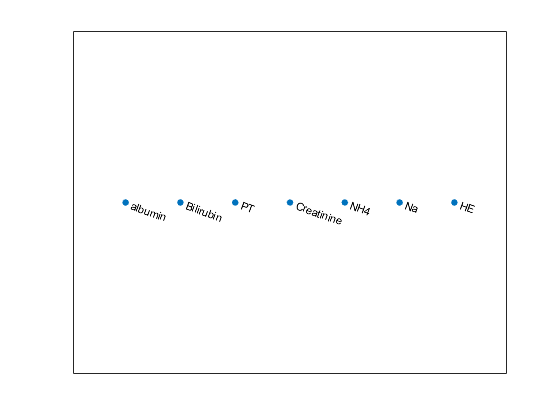

D2 = digraph(sig_R2); % define D2 for plotting digraph

P2 = plot(D2,"NodeLabel",varnames); % plot D2 with variable names for visualization

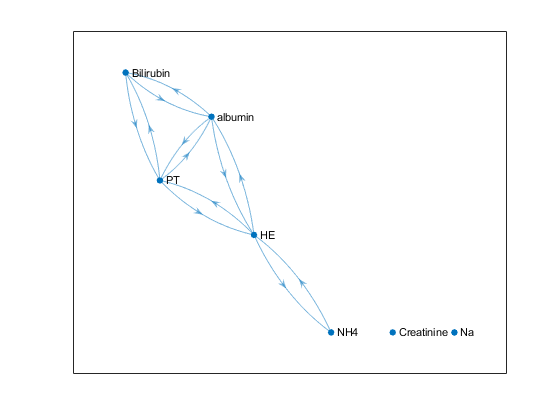

D1 = digraph(sig_R1); % define D2 (reference/normal/survived data) for plotting digraph
P1 = plot(D1,"NodeLabel",varnames); % plot D2 with variable names for visualization

st = D1.Edges.EndNodes; % extract the source and target nodes of the D1/P1 graph
ne = numel(D1.Edges.EndNodes)/2; % extract the number of single edges between all the sources and targets

## **Extract the Ms and Ks of reference/normal data Rs**

for i = 1:ne
    model = fitlm(data1(:,(st(i,1))), data1(:,(st(i,2)))); % fit linear model of variables with significant Rs
    k(:,i) = model.Coefficients.Estimate(1,:); % extract the coefficient k/intercept of the regression models between all sources and targets/correlated pairs of variables
    m(:,i) = model.Coefficients.Estimate(2,:); % extract the slope of the regression models between all sources and targets/correlated pairs of variables
end

## **Compute residuals of egdes/correlated Rs of all datapoints using slope (m) and coefficient (k) of reference data1**

y = [];
yP = [];
for i = 1:ne
    for j = 1:n
        y(j,i) = (data(j,(st(i,2)))); % exttact the real value of variables for each patient
        yP(j,i) = (m(1,i)*(data(j,(st(i,1))))) + (k(1,i)); % extract the expected values of variables for each patients based on the regression model
        Resid(j,i) = abs((yP(j,i)) - (y(j,i))); % compute the residuals i.e. the absolute difference between the real and expected values for each variables for each of the patients
    end
end

## **Compute delta of all data using Rs of reference data**

x = [1:ne]'; % create column numbers for all edges
C = flip(st,2); % horizontally flip "st" to compute delta
stx1 = [st x]; % combine the st with column number of each edge
stx2 = [C x]; % combine flipped st with column number

for i = 1:ne
    for ij = 1:ne
        for j = 1:n
            if stx1(i,(1:2)) == stx2(ij,(1:2)); % for each edge (in a single direction) between two nodes/variables since 1-->2 = 2-->1 extract only for where source s(i) > target t(i)
                denom(j,i) = sqrt((Resid(j,(stx1(i,3))).^2)+((Resid(j,(stx2(ij,3)))).^2)); % use the residuals from each edge (with unique source and target) to compute the denominator of formular for orthogonal residual/delta
                nom(j,i) = (Resid(j,(stx1(i,3))).*(Resid(j,(stx2(ij,3))))); % use the residuals from each edge (with unique source and target) to compute the nominator of formular for orthogonal residual/delta
                delta(j,i) = nom(j,i)/denom(j,i); % combine the unique nominator and sqrt(denominator) to compute the delta for each patient for each edge/variable pairs of the refernce models
            end
        end
    end
end

## Compile the delta columns of all Rs

for df = 1:ne
    if (stx2(df,2)) < (stx2(df,1))
        STX(df,:) = stx2(df,:);
    end
end
STX = STX(any(STX,2),:); % remove rows with all zeros columns

## Use the compiled columns of Rs above to extract directional deltas

for i = 1:numel(STX(:,3))
    deltas(:,i) = delta(:,(STX(i,3))); % extract directional Rs delta into "deltas"
end
Rdelta = deltas;
missing = isnan(deltas); % identify all missing data/delta
deltas(missing) = 0; % convert NaN values to 0 for network parameters calculation
delta = deltas; % update the NaN = 0 values in delta for network topology computation

## **Use the edges from above to construct single direction adjacency matrix**

S = STX(:,1); % extract the source of the significant edges
T = STX(:,2); % extract the targets of the significant edges

## **Compile the variable names of the correlations and deltas**

for i = 1:numel(S)
    combnames{1,i} = append(varnames{:,(S(i,1))} ,'_', varnames{:,(T(i,1))}); % use the Ss and Ts to extract and combine the specific node names for each edges' delta using the extracted variable names
end

## Compute  Centrality Sum, Mean and STD for only patients with complete data

format bank % format the following numbers to see 2 decimal places
for i = 1:n
    if delta(i,:) ~= 0 % for only patients with complete record
        G = digraph(S,T,delta(i,:)); % define digraph G based extracted/correlated Ss and Ts with edges weighted by delta of individual patients
        CENT = 2*(centrality(G,"indegree","Importance",G.Edges.Weight)); % compute "indegree" centrality of G with edges weighted by delta of individual patients
        BTW_cent(i,1) = sum(CENT); % compute the sum of delta-weighted indegree centrality for individual patients
        BTW_cent(i,2) = mean(CENT); % compute the mean of delta-weighted indegree centrality for individual patients
        BTW_cent(i,3) = std(CENT); % compute the standard deviation of delta-weighted indegree centrality for individual patients
    else
        BTW_cent(i,1) = NaN; % for missing  data, omit the sum of delta-weighted indegree centrality for individual patients
        BTW_cent(i,2) = NaN; % for missing  data, omitthe mean of delta-weighted indegree centrality for individual patients
        BTW_cent(i,3) = NaN; % for missing  data, omit the standard deviation of delta-weighted indegree centrality for individual patients
    end
end

adjccy = full(adjacency(G,"weighted")); % visualize the weighted adjacency matrix of last delta-weighted G
cent_Names = ["Cent_Sum", "Cent_Mean", "Cent_STD"]; % compute the centrality arithmetic names/labels
Degree_cent = array2table(BTW_cent,"VariableNames",cent_Names); % combine the centrality arithmetic data and names into a table "Degree_Cent

## Compute Shortest Path Length Sum, Mean and STD

SS = unique(S);
TT = unique(T);
nodes = numel(unique([S T]));
for i = 1:n % for all patients
    for j = 1:numel(unique(S)) % for all unique soource edges
        for ij = 1:numel(unique(T)) % for all unique target edges
            if delta(i,:) ~= 0
                G = digraph(S,T,delta(i,:)); % compute digraph G weighted on delta (i) of all patients
                [PP, dd]= shortestpath(G, SS(j,1), TT(ij,1)); % compute the shortest path from each of all the unique source edges to each  of all the unique target edges weighted on delta (i)
                spl(ij,j) = dd; % save each of all the computed shortest path above as a matrix for individual patient in spl
                d = spl; % save the matrix of spl for each patient in d
                SPL(i,1) = sum(nonzeros(unique(d(~isinf(d)))));  %  find the sum of the real, unique (omit values repeated due flip of S and T), non-zero, non-infinity values of spl/d
                SPL(i,2) = mean(nonzeros(unique(d(~isinf(d))))); %  find the mean of the real, unique (omit values repeated due flip of S and T), non-zero, non-infinity values of spl/d
                SPL(i,3) = std(nonzeros(unique(d(~isinf(d)))));  %  find the std of the real, unique (omit values repeated due flip of S and T), non-zero, non-infinity values of spl/d
                SPL(i,4) = sum((nonzeros(unique(d(~isinf(d)))))./nodes);  %  find the efficiency  of the network by dividing SPL by the nummber of connected nodes within the network
            else
                SPL(i,1) = NaN;  %  find the sum of the real, unique (omit values repeated due flip of S and T), non-zero, non-infinity values of spl/d
                SPL(i,2) = NaN;  %  find the mean of the real, unique (omit values repeated due flip of S and T), non-zero, non-infinity values of spl/d
                SPL(i,3) = NaN;  %  find the std of the real, unique (omit values repeated due flip of S and T), non-zero, non-infinity values of spl/d
                SPL(i,4) = NaN;  %  find the efficiency  of the network by dividing SPL by the nummber of connected nodes within the network
            end
        end
    end
end

SPL_Names = ["SPL_sum", "SPL_mean", "SPL_std", "Efficiency"]; % compute the  names of the  shortest pathlength and the efficiency
SPL = array2table(SPL,"VariableNames",SPL_Names);  % combine the shortest path and efficiency and  insert name labels
% adjccy = full(adjacency(G,"weighted"));  % visualize the  adjacency matrix of the last iterated G from the loop above

## Compute Network Diameter Sum, Mean and STD

for i = 1:n
    if delta(i,:) ~= 0 % for only patients with no missing data and  delta (NaN)
        G = digraph(S,T,delta(i,:));
        diam = (distances(G)); % compute the distances between all weighted connected nodes for each patients (result  is a weigghted matrix)
        DIAM(i,:) = max(diam(~isinf(diam))); % extract the  max distance between any two connected nodes for all patients, ignoring the "inf" output
    else
        DIAM(i,:) = NaN;
    end
end

DIAM = array2table(DIAM, "VariableNames","Diameter"); % label the network diameter

## Output Deltas with Correlated Variable Names and Categories as CSV or XLSX

deltaname = array2table(Rdelta,"VariableNames",combnames);  % combine the deltas of patients with the appended names of the connected variables
CAT = array2table(category, "VariableNames", CATname);  % exttract and label  the categories of  patients  based on predefined classes
NetworkParameter = [Degree_cent SPL DIAM CAT]; % combine all  nnamed  network parameters
OUTPUT = [deltaname NetworkParameter];  % combine the labelled deltas and network parameters of all patients into a single file "OUTPUT"
[finaldata, labeldata] = KapMya(OUTPUT);
finale = array2table(finaldata,"VariableNames",labeldata);
finale = [finale CAT];
writetable(finale, append('OUTPUT_', date, '.csv')); % write the output into a csv file with date in which the result is generated.

## Plot Correlated Variables of categories (outcomes) to visualise deviation from refernce model

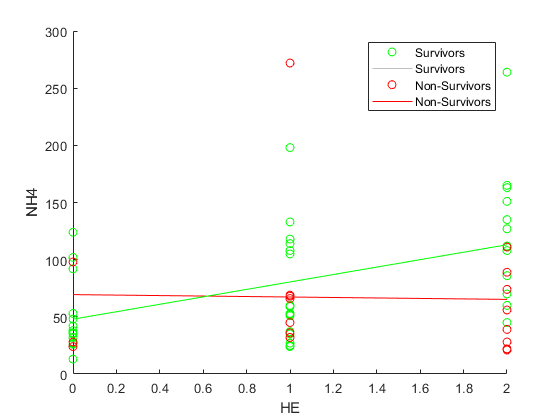

doodlemax = ne/2; % define the maximum number of correlation for number slider
doodle = 6; % create a doodle with numeric slider
scatter(data1(:,(S(doodle,1))), data1(:,(T(doodle,1))), "green",'o'); % create scatter plot of reference data with green color
lsline; % insert trendline with green color
xl = xlabel(varnames(1, S(doodle,1)));
yl = ylabel(varnames(1, T(doodle,1))); % insert the  variable names  based on the columns been plotted
hold on
scatter(data2(:,(S(doodle,1))), data2(:,(T(doodle,1))), "red",'o'); % create scatter plot of treatment/study data with green color
h = lsline; % insert trendline with green color
set(h(1),'color','r')
set(h(2),'color','g') % set the colors of the two trendlines
legend("Survivors", "Survivors","Non-Survivors", "Non-Survivors") % insert  figure legend  for clarity
hold off